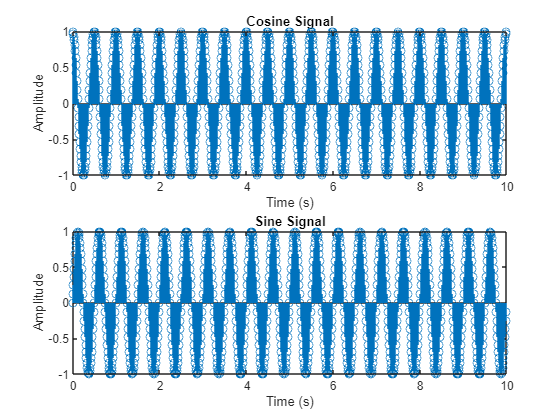

% Parameters
f0 = 2; % Frequency of the sinusoidal signal (chosen as 2 Hz)
time_periods = 10; % Number of time periods
sampling_frequency = 100; % Sampling frequency (samples per second)
total_samples = time_periods * sampling_frequency; % Total number of samples
time_axis = (0:total_samples-1) / sampling_frequency; % Time axis
% Generate discrete time sinusoidal signals
x1 = cos(2*pi*f0*time_axis); % Cosine signal
x2 = sin(2*pi*f0*time_axis); % Sine signal

% Plotting the signals
subplot(2, 1, 1);
stem(time_axis, x1);
title('Cosine Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2, 1, 2);
stem(time_axis, x2);
title('Sine Signal');
xlabel('Time (s)');
ylabel('Amplitude');

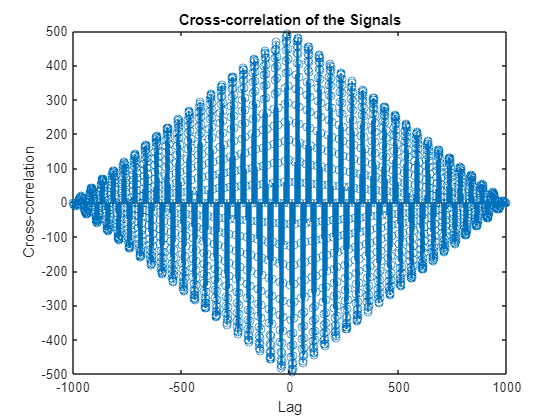


% Find the cross-correlation of the two signals
cross_corr = xcorr(x1, x2);

% Define the lag axis for cross-correlation
lag_axis = -(length(x1)-1):(length(x1)-1);

% Plotting the cross-correlation
figure;
stem(lag_axis, cross_corr);
title('Cross-correlation of the Signals');
xlabel('Lag');
ylabel('Cross-correlation');